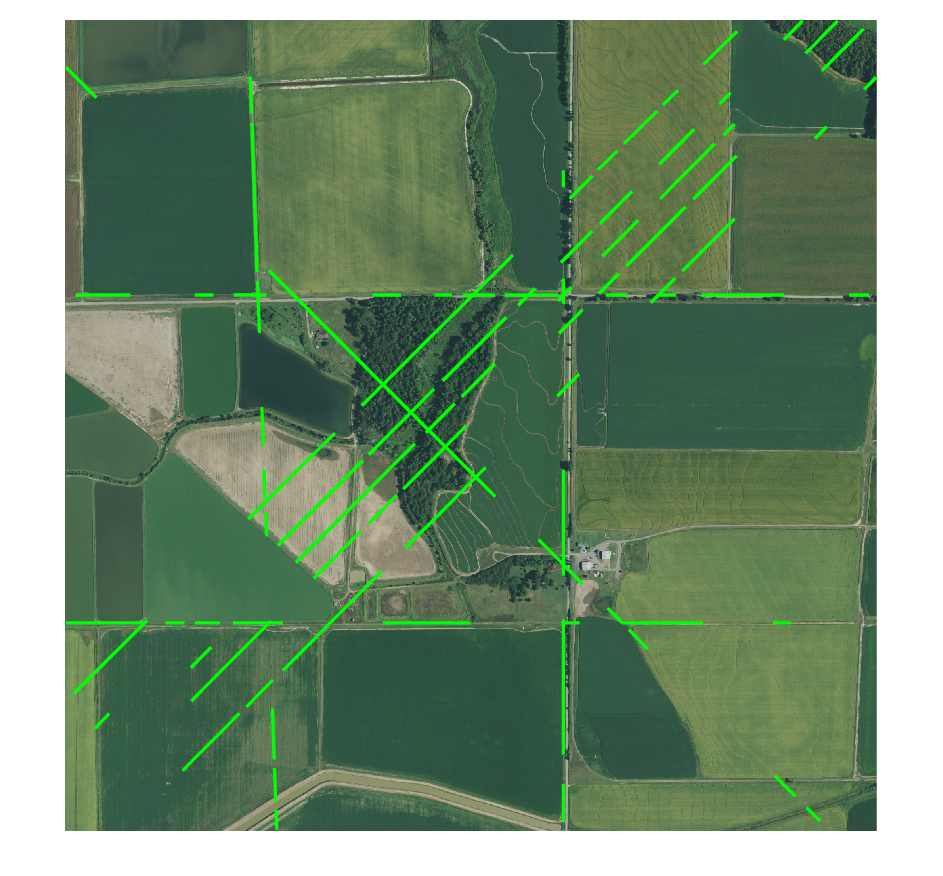

path = "C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Update-2\Dataset\Development\field.jpg";
pathGT = "C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Update-2\Dataset\GroundTruth\fieldGT.tif";
img = imread(path);
imgGT = imread(pathGT);
grayImage = rgb2gray(img);
edges = edge(grayImage, 'canny');
[H, theta, rho] = hough(edges);
peaks = houghpeaks(H, 10);
lines = houghlines(edges, theta, rho, peaks);
imshow(img), hold on
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
end
hold off